# Test the elevation map sensor model on the campus of the University of Freiburg

Register the map and the sensor point cloud.

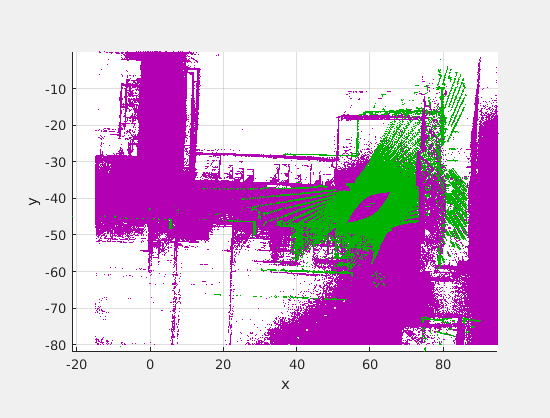

% Read the map point cloud.
pcMap = removeInvalidPoints(pcread('pcd/data/campus_freiburg.pcd'));
pcMap = select(pcMap, findPointsInROI(pcMap, [-15, 95; -80, 0; -Inf, +Inf]));

% Read the sensor point cloud.
pcSensor = removeInvalidPoints(pcread('pcd/data/bonirob_campus.pcd'));
tfinit = [quat2rotm([1, -0.009, -0.000, -0.027]), [60.725; -41.839; 0.780]; 0, 0, 0, 1];
pcSensor = pctransform(pcSensor, ht2affine3d(tfinit));

% Compare map and sensor point cloud.
pcshowpair(pcMap, pcSensor); labelaxes; view(0, 90)

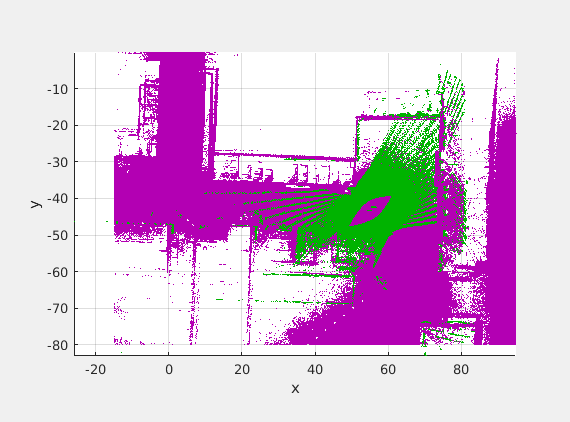


% Register the point clouds using ICP.
tfreg = pcregrigid(pcdownsample(pcSensor, 'gridAverage', 0.3), pcdownsample(pcMap, 'gridAverage', 0.3));
pcSensorReg = pctransform(pcSensor, tfreg);
pcshowpair(pcMap, pcSensorReg); labelaxes; view(0, 90)

Create an elevation map from the map point cloud.

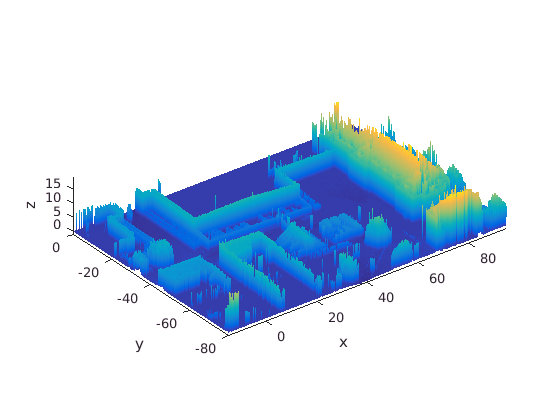

% Create the elevation map and fill the gaps in the map.
em = setprior(fillnan(elevationmap(pcMap, 0.05), [5,5]), 0);
em.plot

Shift the scan and for each offset compute how well the scan matches the map.

% Define the offsets in x and y direction.
x = -20 : 0.1 : +20;
y = -20 : 0.1 : +20;
nx = numel(x);
ny = numel(y);

% Initialize the matrix that stores the mean z difference.
d = NaN(nx, ny);

% Loop over all offsets.
parfor ix = 1 : nx
    for iy = 1 : ny
        % Extract point coordinates from the scan.
        psensor = reshape(pcsens.Location(:), pcsens.Count, 3, 1);
        
        % Shift the scan horizontally.
        psensor = psensor + repmat([x(ix),y(iy),0], size(psensor,1), 1);
        
        % Adjust the z coordinate of the scan origin.
        ifin = all(isfinite(psensor(:,1:2)), 2);
        psensor(:,3) = psensor(:,3) - mean(em.diff(psensor), 'omitnan');
        
        % Compute the difference in z for all points of the scan.
        % Allow only positive values, as negative differences mean the scan
        % hit an object and the corresponding point is correct.
        dz = constrain(em.diff(psensor), [0,+Inf]);
        
        % Compute the fraction of unmatched points.
        nanfrac(ix,iy) = sum(isnan(dz)) / numel(dz);
        
        % Compute the mean difference along z between the elevation map and 
        % the scan.
        if nanfrac(ix,iy) < 0.1
            d(ix,iy) = mean(dz, 'omitnan');
        end        
    end
    
    % Advance the progress bar.
    progressbar
end


Plot results.

% Plot the mean z distance for all offsets.
fig = figure('Name', 'Mean distance in z');
surf(x, y, d', 'EdgeColor', 'none')
daspect([1,1,0.01])
labelaxes